# MATLAB Instruction - Farfield evaluation using SGF

# **Farfield evaluated using SGF**

## **Theory**

The electric field radiated by an electric current can be expressed as follows:

when considering stationary phase point, the farfield can be evaluated asmptotically:

where $\left(x^{\prime } ,y^{\prime } ,z^{\prime } \right)$is the source position while $\left(x,y,z\right)$ is the observation position, $k_{\textrm{xs}} =k\sin \theta \cos \phi ,k_{\textrm{ys}} =k\sin \theta \sin \phi ,k_{\textrm{zs}} =k\cos \theta \;$rerepresent the dominant plane wave,$\vec{J} \left(k_x ,k_y \right)$ is the FT of the current distribution, and ${\tilde{G} }^{\textrm{ej}}$ is the dyadic SGF for electric currents 


$${\bar{\bar{G} } }^{{\;}^{\textrm{ej}} } \left(k_x ,k_y \right)=-\frac{\zeta \;}{2{\textrm{kk}}_z }\left\lbrack \begin{array}{ccc}
k^2 -k_x^2  & -k_x k_y  & -k_x \left(\pm k_z \right)\\
-k_x k_y  & k^2 -k_y^2  & -k_y \left(\pm k_z \right)\\
-k_x \left(\pm k_z \right) & -k_y \left(\pm k_z \right) & k^2 -k_z^2 
\end{array}\right\rbrack$$


**Directivity**

The directivity of a farfield can be obtained as:

where $U\left(\theta ,\phi \right)$ is the radiation intensity:

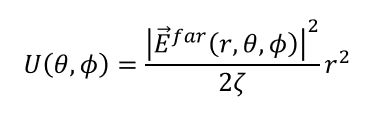

and $P_{\textrm{rad}}$ is the total radiated power:

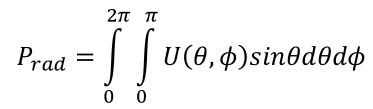

## MATLAB Implementation

To evaluate the farfield radiated by a current, we should perform the following steps:

**(1)** Calculate the dyadic SGF. **(2)** Obtain the FT of the current distribution. **(3)** Use Eq.2 to evaluate the farfield. **(4) **Estimate the directivity of the farfield.

The above steps are applicable for any source so it would be convenient to build separate routines for these steps, and then reuse it for different applications. Today you should learn how to build the routines:

**(1)**  ej_SGF = **EJ_SGF**(er, k, kx, ky)

**(2)** Jx = **FTCurrent**(k, er, kx, ky, l, w)

**(3)** [Eth, Eph] = **farfield**(k, R_FF, TH, PH, kz, Gxx, Gyx, Gzx, Jx)

**(4)** [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r)

# Q1 (3 points): Elementary electric source

Write a Matlab routine to calculate the free space *Spectral Green’s Function* (SGF) of an elementary electric source oriented along $\hat{x}$ and placed at the origin of the reference system.

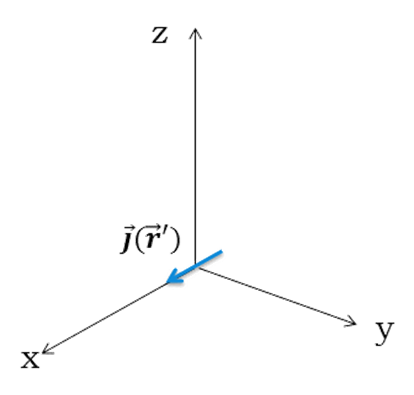

### 1. Plot the x-, y-, and z-components of the SGF, given the $\hat{x}$-oriented current. 

Both real and imaginary parts should be plotted. Consider$f=30$ GHz, $k_x \in \left\lbrack 0,3k_0 \right\rbrack$ and $k_y =0$. 

**Routines to calculate SGF**

It would be conveninent to write a routine to calculate the complete SGF for electric currents: [ej_SGF] = **EJ_SGF**(er, k, kx, ky)


$${\bar{\bar{G} } }^{{\;}^{\textrm{ej}} } \left(k_x ,k_y \right)=-\frac{\zeta \;}{2{\textrm{kk}}_z }\left\lbrack \begin{array}{ccc}
k^2 -k_x^2  & -k_x k_y  & -k_x \left(\pm k_z \right)\\
-k_x k_y  & k^2 -k_y^2  & -k_y \left(\pm k_z \right)\\
-k_x \left(\pm k_z \right) & -k_y \left(\pm k_z \right) & k^2 -k_z^2 
\end{array}\right\rbrack$$


Note that $k_z$ should be defined uniquely as follows:

**Elementary source in free space**

In this case,$\vec{j} \left(x,y,z\right)=\delta \left(x\right)\delta \left(y\right)\delta \left(z\right)\hat{x}$, and its FT is $\vec{J} \left(k_x ,k_y \right)=\hat{x}$.

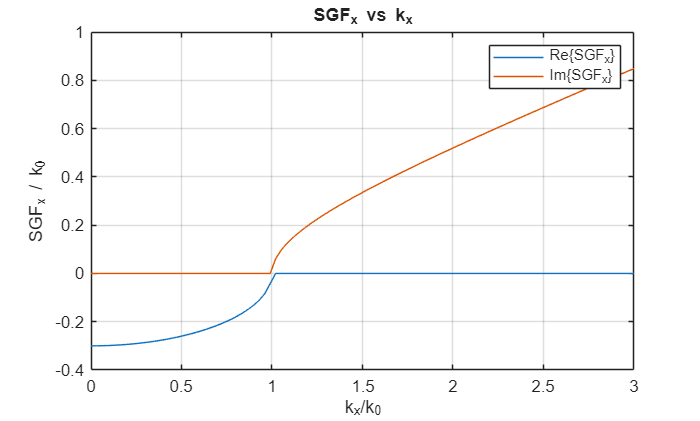

% Given parameters
f      = 30e9; 
lambda_0 = 3e8 / f; 
k0     = 2 * pi / lambda_0;  
er     = 1;

%Define the mesh (not really a mesh in this case)
num_kx = 101;
num_ky = 1;
k_x    = linspace(eps, 3*k0, num_kx); 
k_y    = 0;
[KX, KY] = meshgrid(k_x, k_y);

%Given current density: unit vector towards positive x
J = zeros([size(KX), 3]);   % Ny x Nx x 3
J(:,:,1) = 1;               % Jx = 1 everywhere, Jy=Jz=0

%Apply SGF
ej_SGF = EJ_SGF(er, k0, KX, KY);

SGF_x = ej_SGF(:,:,1,1).*J(:,:,1) + ej_SGF(:,:,1,2).*J(:,:,2) + ej_SGF(:,:,1,3).*J(:,:,3);
SGF_y = ej_SGF(:,:,2,1).*J(:,:,1) + ej_SGF(:,:,2,2).*J(:,:,2) + ej_SGF(:,:,2,3).*J(:,:,3);
SGF_z = ej_SGF(:,:,3,1).*J(:,:,1) + ej_SGF(:,:,3,2).*J(:,:,2) + ej_SGF(:,:,3,3).*J(:,:,3);

%Plot the results
%Warning: this part I assume the mesh is 1D.
figure;
plot(KX/k0, real(SGF_x)/k0, KX/k0, imag(SGF_x)/k0);
grid on;
xlabel('k_x/k_0'); ylabel('SGF_x / k_0');
legend('Re\{SGF_x\}','Im\{SGF_x\}');
title('SGF_x vs k_x');

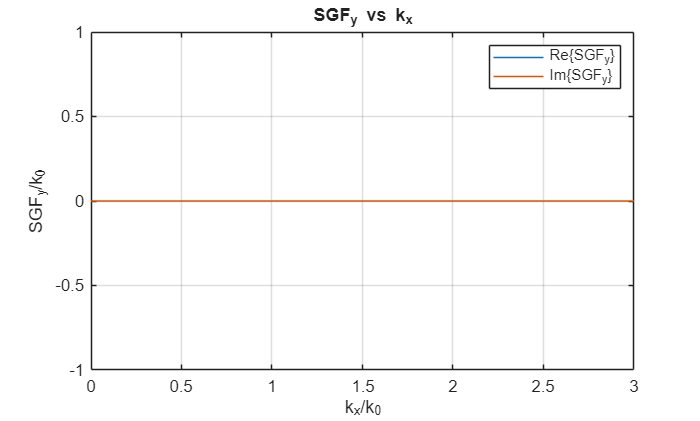


figure;
plot(KX/k0, real(SGF_y)/k0, KX/k0, imag(SGF_y)/k0);
grid on;
xlabel('k_x/k_0'); ylabel('SGF_y/k_0');
legend('Re\{SGF_y\}','Im\{SGF_y\}');
title('SGF_y vs k_x');

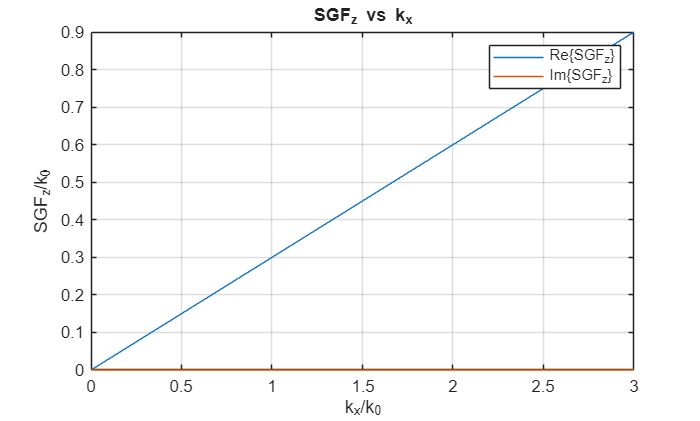



figure;
plot(KX/k0, real(SGF_z)/k0, KX/k0, imag(SGF_z)/k0);
grid on;
xlabel('k_x/k_0'); ylabel('SGF_z/k_0');
legend('Re\{SGF_z\}','Im\{SGF_z\}');
title('SGF_z vs k_x');

### **2. In which region of the spectrum is the x-component imaginary? Justify your answer with the plot and the SGF expression.**

When k_x >= k, the x component becomes imaginary; this can be found in the figure. Addtionally, in the SGF expression, we notice that if kx > k, then k^2 - k_x^2 < 0. Since ky = 0, k^2 - k_x^2 - k_y^2 < 0 so - (k^2 - k_x^2 - k_y^2) > 0 resulting a imaginary k_z which leads to a imaninary x-component. On the other hand if k_x < k then k_z can become real. 

# Q2 (4 points): Farfield of a dipole

Write a Matlab program to calculate the far field radiated in the upper hemisphere by the  dipole shown in the figure using the free space SGF. 

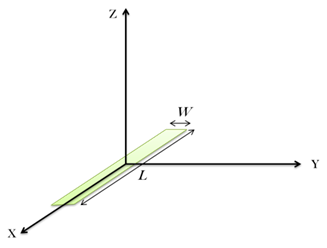

### 1. 1D plot of the farfield in main planes

Consider a dipole: $L=\lambda_0 /2,w=\lambda_0 /40$ @ 30 GHz, and calculate the far field (total field) for $\phi =0^{\circ \;} /{{45}^{\circ \;} /90}^{\circ \;}$.

**Farfield evaluated using SGF**

**Step 1:  Calculate the dyadic SGF**

Build the dyad for electric current: [ej_SGF] = **EJ_SGF**(er, k, kx, ky)

% Now we actually need a 2D mesh
% Given parameters
f      = 30e9; 
lambda_0 = 3e8 / f; 
k0     = 2 * pi / lambda_0;  
er     = 1;

%Define the mesh
num_th = 401;
num_ph = 101;

theta = linspace(eps, pi / 2, num_th); % radian
phi   = linspace(eps, pi * 2, num_ph);
[TH, PH] = meshgrid(theta, phi);


R_FF = 1; % radius of 1 m
KX = k0 * sin(TH) .* cos(PH); % X 
KY = k0 * sin(TH) .* sin(PH); % Y
KZ = k0 * cos(TH);            % Z


ej_SGF = EJ_SGF(er, k0, KX, KY);

**Step 2:  Calculate the FT of the current distribution**

For dipole antennas, we can approximate the spatial current distribution using the current distribution along an open circuited transmission line. This distribution can be expressed in general as follows:

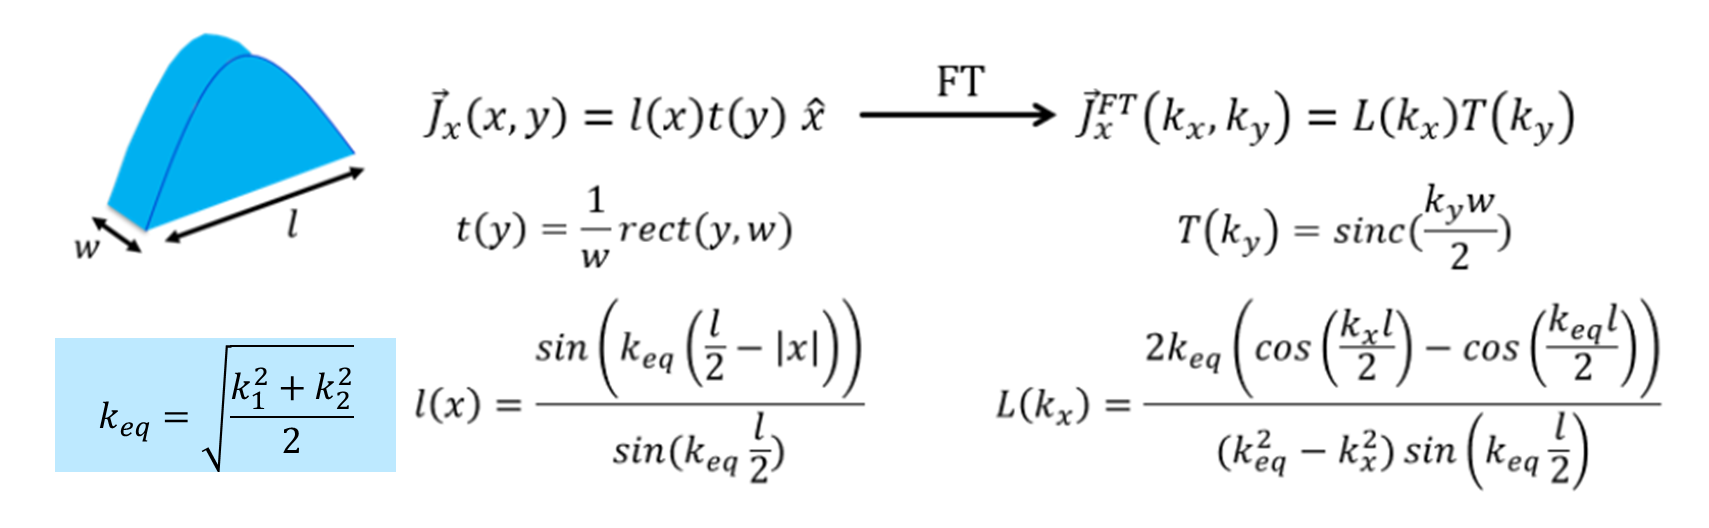

Write a routine to calculate the FT of currents: Jx = **FTCurrent**(k0, er, kx, ky, l, w)

l = lambda_0 / 2;
w = lambda_0 / 40;

Jx = FTCurrent(k0, er, KX, KY, l, w);

**Step 3:  Evaluate the farfield (total field)** 

Calculate the FF in Eth and Eph and plot the total field: 

[Eth, Eph] = **farfield**(k0, R_FF, TH, PH, Gxx, Gyx, Gzx, Jx, kz, z)

Gxx = ej_SGF(:,:,1,1);
Gyx = ej_SGF(:,:,2,1);
Gzx = ej_SGF(:,:,3,1);


[Eth, Eph] = farfield(k0, R_FF, TH, PH, KZ, Gxx, Gyx, Gzx, Jx);

### 2. Farfield in the upper medium (z>0) plotted using UV representation.

In UV plane: $U=\sin \theta \;\cos \phi ,V=\sin \theta \;\sin \phi$.

Please use a representation such as 'surface' (with a top view), 'pcolor', or 'imagesc', and use a dynamic range of 10 dB

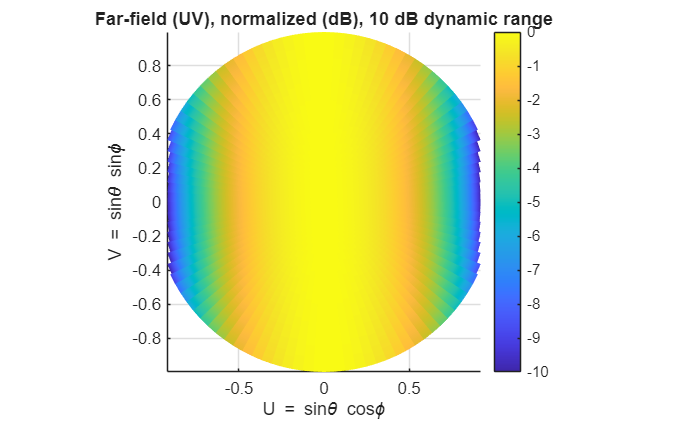

Eabs = sqrt(abs(Eth).^2 + abs(Eph).^2);
U = sin(TH).*cos(PH);
V = sin(TH).*sin(PH);
Edb = 20*log10(Eabs ./ max(Eabs(:)));   % normalized to 0 dB peak
Edb(Edb < -10) = NaN;                   % clamp to 10 dB dynamic range

figure;
surf(U, V, Edb, 'EdgeColor', 'none');
view(2); axis equal tight;
xlabel('U = sin\theta cos\phi');
ylabel('V = sin\theta sin\phi');
colorbar;
clim([-10 0]);
title('Far-field (UV), normalized (dB), 10 dB dynamic range');

### 3. Evaluated the directivity at broadside in dB as a funciton of frequency 

Calculate the FF as a function of frequency and evaluate the directivity for each frequency. The dipole dimensions are: $L=5$ mm, $W=0\ldotp 25$mm.

**Directivity**

The directivity of a farfield can be obtained as:

where $U\left(\theta ,\phi \right)$ is the radiation intensity:

and $P_{\textrm{rad}}$ is the total radiated power:

We can build a routine to calculate the directivity: [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r)

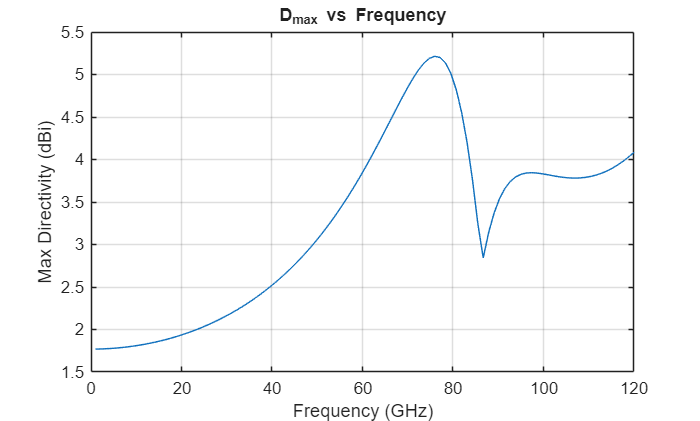

% We try to evaluate the relationship between f and max_directivity
c0 = 3e8;

l = 5e-3;     
w = 0.25e-3;    

R_FF = 1000;      
er = 1;      

% frequency sweep
f = linspace(1e9, 120e9, 101);     
Nf = numel(f);

% angular grid (upper hemisphere)
Nth = 181;
Nph = 361;
[PH, TH] = meshgrid(linspace(eps,2*pi,Nph), linspace(eps,pi/2,Nth));
dth = (pi/2)/(Nth-1);
dph = (2*pi)/(Nph-1);

Prad_vs_f = zeros(Nf,1);
Dmax_vs_f = zeros(Nf,1);

% -------------------- loop over frequency --------------------
for ii = 1:Nf
    k0 = 2*pi*f(ii)/c0;
    k = k0*sqrt(er);

    KX = k .* sin(TH).*cos(PH);
    KY = k .* sin(TH).*sin(PH);
    KZ = k .* cos(TH);

    Jx  = FTCurrent(k0, er, KX, KY, l, w);  

    G = EJ_SGF(er, k0, KX, KY);

    Gxx = G(:,:,1,1);
    Gyx = G(:,:,2,1);
    Gzx = G(:,:,3,1);

    [Eth, Eph] = farfield(k0, R_FF, TH, PH, KZ, Gxx, Gyx, Gzx, Jx);

    E_tot = sqrt(abs(Eth).^2 + abs(Eph).^2);

    [Dir_temp, Prad_temp] = Directivity(E_tot, TH, dth, dph, er, R_FF);

    %The following term depends on the mesh grid, Directivity function 
    %assumes full mesh coverage in this case only half of the space is 
    %covered for the power, therefore, they have been scaled to compensate
    %the mismatch
    Dir = Dir_temp / 2;
    Prad = Prad_temp * 2;

    Prad_vs_f(ii) = Prad;
    Dmax_vs_f(ii) = max(Dir(:));
end

% -------------------- plots --------------------
figure; plot(f/1e9, 10*log10(Dmax_vs_f)); grid on;
xlabel('Frequency (GHz)'); ylabel('Max Directivity (dBi)'); title('D_{max} vs Frequency');

It seems like the directivity is way too high. For a dipole antenna the value should be around 2.3 dBi but I have 8 dB at the design frequency, it is way too high so I probably did something wrong in my old calculation. 

# Q3 (3 points): Dipole with a backing reflector

Consider a dipole: $L=\lambda_0 /2,w=\lambda_0 /40$ @ 30 GHz, that is radiating in the presence of an infinite PEC plane as shown in the figure.

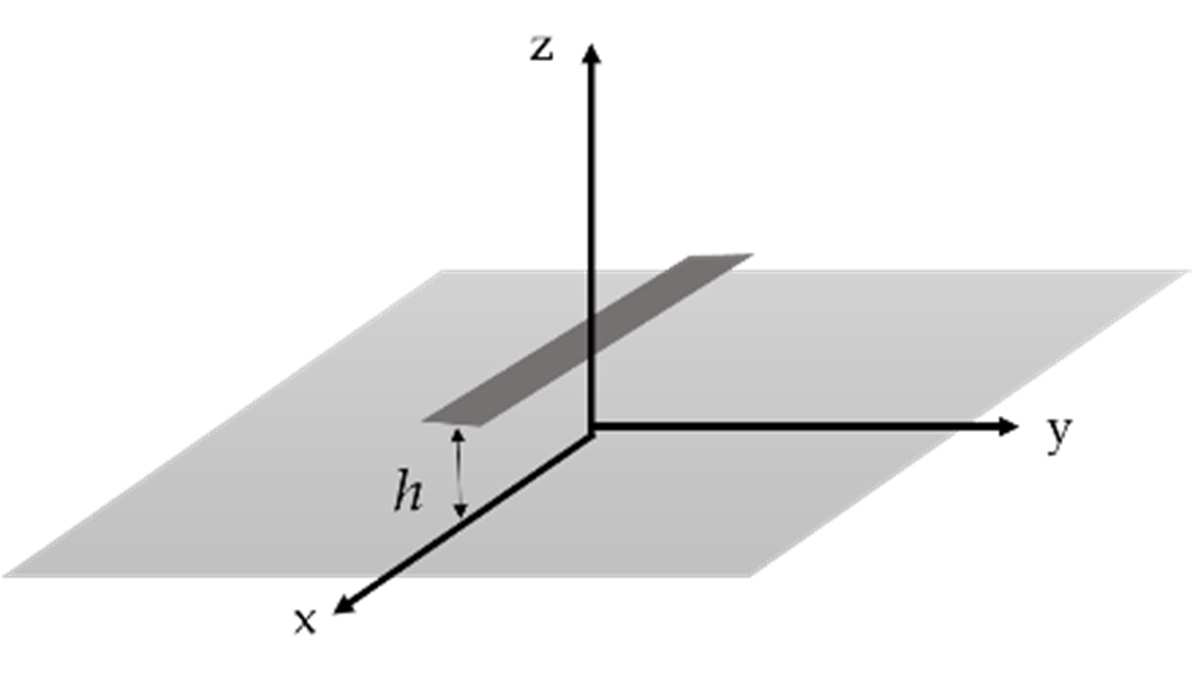

### 1. Plot 1D the farfield along the main planes and compare it to the one in Q2.

Here we consider $h=7\ldotp 5$ mm. To remove the PEC plane and use free space's GF, we can resort to image theorem. 

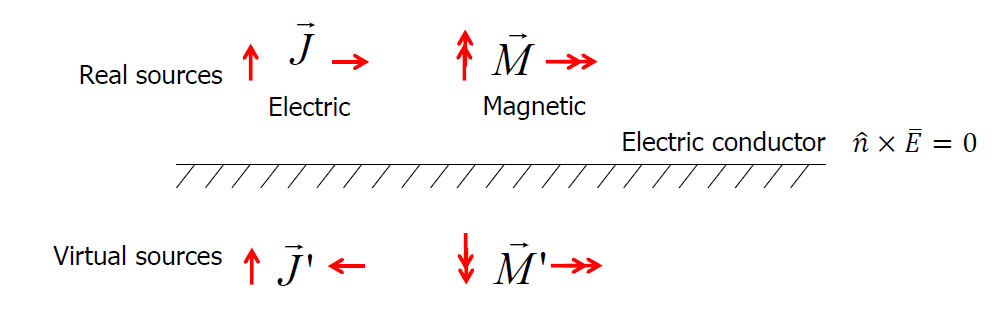

Before assessing the farfield numerically, please write down the analytical expression of the current spectrum.


$$J_{\textrm{tot}} =l\left(x\right)t\left(x\right)\delta \left(z-h\right)\hat{x} -l\left(x\right)t\left(x\right)\delta \left(z+h\right)\hat{x} \;\ldotp \;$$


**Step 1:  Calculate the dyadic SGF**

% Now we actually need a 2D mesh
% Given parameters
f      = 30e9; 
lambda_0 = 3e8 / f; 
k0     = 2 * pi / lambda_0;  
er     = 1;

num_th = 401;
num_ph = 401;



theta = linspace(eps, pi/2, num_th);      
phi   = linspace(eps, 2*pi, num_ph);      
[TH, PH] = meshgrid(theta, phi);          



R_FF = 1; % radius of 1 m
KX = k0 * sin(TH) .* cos(PH); % X: note that X,Y,Z are non-uniform parameters while TH, PH are uniform 
KY = k0 * sin(TH) .* sin(PH); % Y
KZ = k0 * cos(TH);            % Z


ej_SGF = EJ_SGF(er, k0, KX, KY);

**Step 2:  Calculate the FT of the current distribution**

l = lambda_0 / 2;
w = lambda_0 / 40;
h = 7.5e-3;
Jx_single = FTCurrent(k0, er, KX, KY, l, w);
%FT of the functions
Jx_two = Jx_single .* (exp(1i.*KZ*h) - exp(-1i.*KZ*h));   


**Step 3:  Evaluate the far field (total field)**

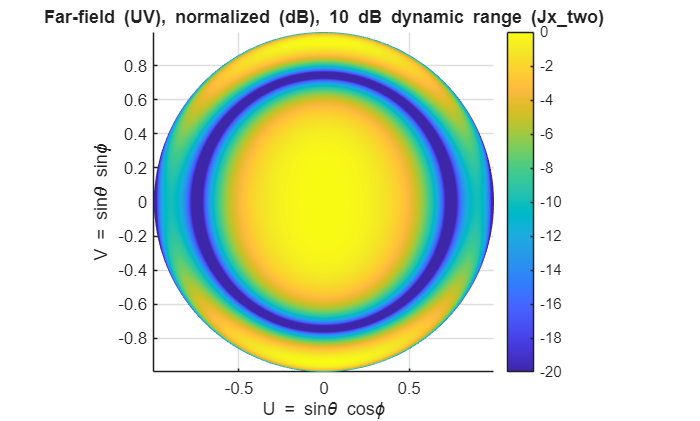

Gxx = ej_SGF(:,:,1,1);
Gyx = ej_SGF(:,:,2,1);
Gzx = ej_SGF(:,:,3,1);

Eabs = sqrt(abs(Eth).^2 + abs(Eph).^2);
U = sin(TH).*cos(PH);
V = sin(TH).*sin(PH);
Edb = 20*log10(Eabs ./ max(Eabs(:)));   % normalized to 0 dB peak
Edb(Edb < -10) = NaN;                   % clamp to 10 dB dynamic range

[Eth, Eph] = farfield(k0, R_FF, TH, PH, KZ, Gxx, Gyx, Gzx, Jx_two);
Eabs_two = sqrt(abs(Eth).^2 + abs(Eph).^2);
Edb_two = 20*log10(Eabs_two ./ max(Eabs_two(:)));   % normalized to 0 dB peak
Edb_two(Edb_two < -20) = -20;                       % clamp to 10 dB dynamic range

figure;
surf(U, V, Edb_two, 'EdgeColor', 'none');
view(2); axis equal tight;
xlabel('U = sin\theta cos\phi');
ylabel('V = sin\theta sin\phi');
colorbar;
clim([-20 0]);
title('Far-field (UV), normalized (dB), 10 dB dynamic range (Jx\_two)');

### 3. Evaluate the directivity at broadside (linear scale) as a function of the distance $\mathit{\mathbf{h}}$ from the ground plane 

Plot the result from $h=\lambda_0 /10$ to $h={2\lambda }_0$. Please express the x-axis in terms of the wavelength.

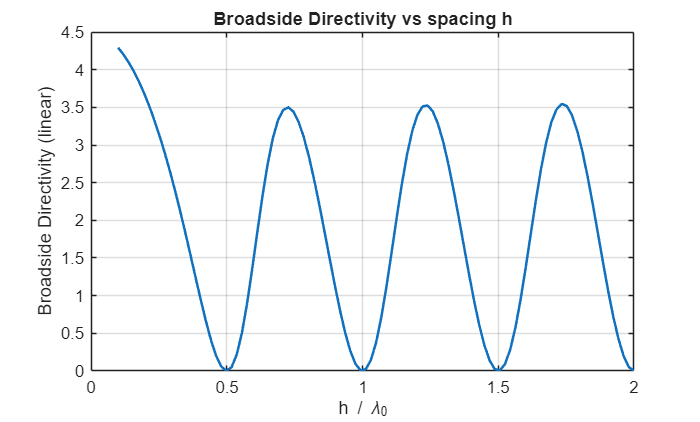

f = 30e9;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2 * pi / lambda_0;

er  = 1;   

num_th = 401;
num_ph = 401;

dth = (pi)/(num_th-1);
dph = (2*pi)/(num_ph-1);

theta = linspace(eps, pi, num_th);      
phi   = linspace(eps, 2*pi, num_ph);      
[TH, PH] = meshgrid(theta, phi);          

k = k0*sqrt(er);
KX = k .* sin(TH) .* cos(PH);
KY = k .* sin(TH) .* sin(PH);
% KZ = k .* cos(TH);

kz = -1i .* sqrt( -(k.^2 - KX.^2 - KY.^2) );


l = lambda_0/2;
w = lambda_0/40;

R_FF = 1;

G = EJ_SGF(er, k0, KX, KY);        % size: Nth x Nph x 3 x 3 
Gxx = G(:,:,1,1);
Gyx = G(:,:,2,1);
Gzx = G(:,:,3,1);

Jx_single = FTCurrent(k0, er, KX, KY, l, w);

Nh = 101;
h_vec = linspace(lambda_0/10, 2*lambda_0, Nh);

Dmax = zeros(size(h_vec));

for ii = 1:Nh
    h = h_vec(ii);

    Jx_two = Jx_single .* 2j .* sin(kz .* h);

    [Eth, Eph] = farfield(k0, R_FF, TH, PH, kz, Gxx, Gyx, Gzx, Jx_two);

    E_tot = sqrt(abs(Eth).^2 + abs(Eph).^2);

    [Dir, ~] = Directivity(E_tot, TH, dth, dph, er, R_FF);

    Dmax(ii) = Dir(1,1);   
end


figure;
plot(h_vec/lambda_0, Dmax, 'LineWidth', 1.5);
grid on;
xlabel('h / \lambda_0');
ylabel('Broadside Directivity (linear)');
title('Broadside Directivity vs spacing h');

In which domain do you integrate to calculate the radiated power? (**Hint: you have applied the image theorem...**)

-> only upper half plane due to PEC material 

Consider the spectrum calculated in Q3.1. For which values of $h$ do you expect a null at broadside (please think about the correct expression of $k_z$)? 

-> the array factor involves sin(kz h) so I would expect when k_z * h = n* pi we have a null at broadside. 

What is the power radiated for $h=0$? Please use the spectrum and/or the image. Verify it numerically.  

-> I assume there will be no power because the source and the image current density cancel each other. 

**Note: Please explain all the figures and results!**